# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `layers`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 08-Apr-2024 20:06:27

## Load Initial Parameters

Load parameters for network initialization. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("/Users/sakshidhomne/Documents/Fatty Liver Project/FL_classifier1");

## Import Data

Import training and validation data.

imdsTrain = imageDatastore("Dataset_v3","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7);

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([227 227 3],imdsTrain);
augimdsValidation = augmentedImageDatastore([227 227 3],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("rmsprop",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.001,...
    "Shuffle","every-epoch",...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Array of Layers

layers = [
    imageInputLayer([227 227 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    fullyConnectedLayer(20,"Name","fc")
    batchNormalizationLayer("Name","batchnorm")
    convolution2dLayer([3 3],32,"Name","conv_1","Padding","same")
    reluLayer("Name","relu_1")
    fullyConnectedLayer(4,"Name","fc_1")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Train Network

Train the network using the specified options and training data.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       32.81% |       46.06% |       1.3833 |       1.2825 |          0.0010 |
|      17 |          50 |       00:02:31 |      100.00% |       60.00% |       0.0523 |       1.1171 |          0.0010 |
|      30 |          90 |       00:04:26 |      100.00% |       50.91% |       0.0074 |       1.6798 |          0.0010 |
|=========================================================================================

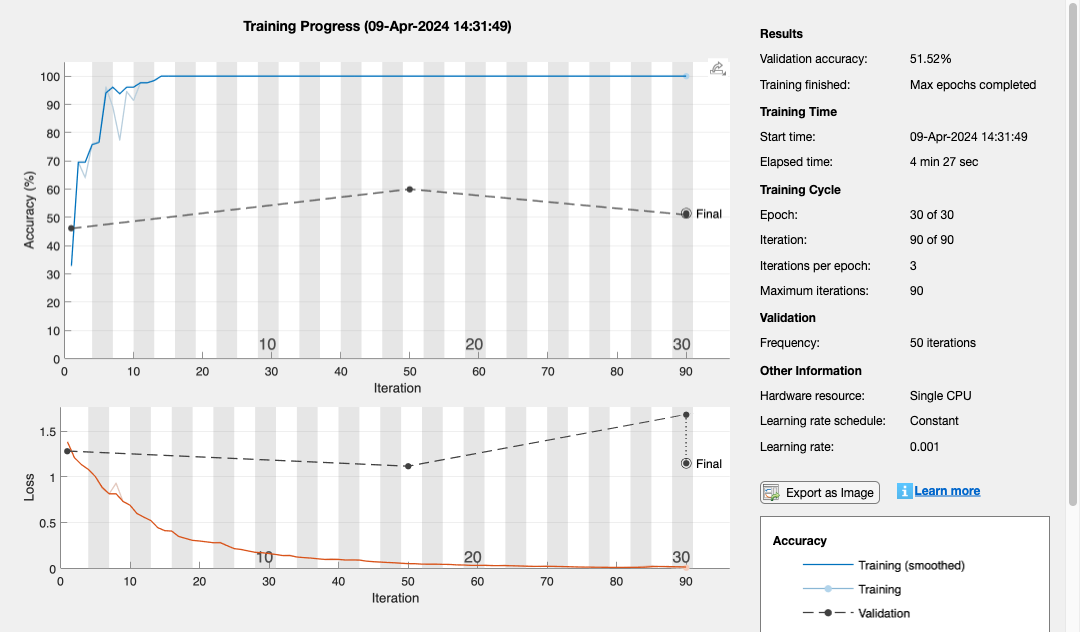

[net, traininfo] = trainNetwork(augimdsTrain,layers,opts);

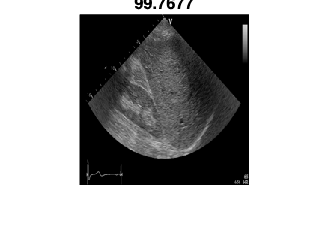

I = imread('/Users/sakshidhomne/Documents/MATLAB/TestImages/NORMAL_TEST/NM1.png');
R = imresize(I, [227, 227]);
[Label, Probability] = classify(net, R);
figure;
imshow(R);
title({char(Label), num2str(max(Probability)*100, 6) })

% /Users/sakshidhomne/Documents/MATLAB/TestImages/GRADE1_TEST/G1_1.png

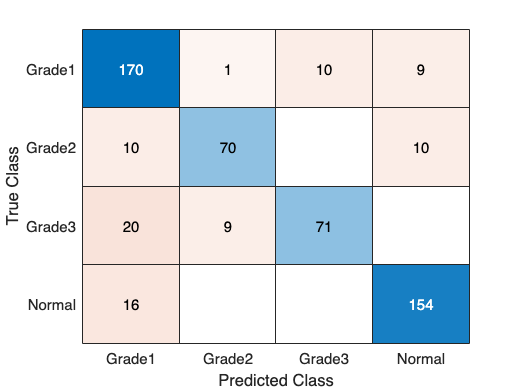

% Load the test dataset
imdsTest = imageDatastore("Dataset_v3", "IncludeSubfolders", true, "LabelSource", "foldernames");

% Resize the test images to match the network input layer
augimdsTest = augmentedImageDatastore([227 227 3], imdsTest);

% Classify the test images using the trained network
predictedLabels = classify(net, augimdsTest);

% Get the actual labels of the test images
actualLabels = imdsTest.Labels;

% Plot the confusion matrix
figure;
confusionchart(actualLabels, predictedLabels);

% Load the test dataset
imdsTest = imageDatastore("Dataset_v3", "IncludeSubfolders", true, "LabelSource", "foldernames");

% Resize the test images to match the network input layer
augimdsTest = augmentedImageDatastore([227 227 3], imdsTest);

% Classify the test images using the trained network
predictedLabels = classify(net, augimdsTest);

% Get the actual labels of the test images
actualLabels = imdsTest.Labels;

% Calculate accuracy
accuracy = sum(predictedLabels == actualLabels) / numel(actualLabels);

% Calculate confusion matrix
confMat = confusionmat(actualLabels, predictedLabels);

% Calculate precision, recall, and F1 score
precision = diag(confMat) ./ sum(confMat, 1)';
recall = diag(confMat) ./ sum(confMat, 2);
f1Score = 2 * (precision .* recall) ./ (precision + recall);

% Display the results
disp("****** The Results ******")

****** The Results ******


disp("Accuracy: " + accuracy);

Accuracy: 0.85455


disp("Precision: " + mean(precision));

Precision: 0.86755


disp("Recall: " + mean(recall));

Recall: 0.83956


disp("F1 Score: " + mean(f1Score));

F1 Score: 0.85123
